           В волноводе квадратного сечения с размерами a = b = 7,2 мм, заполненном воздухом, стенки которого сделаны из материала с проводимостью $\sigma$ = (0,5·M+0,01·N)·10^7 См/м, распространяется волна типа Н11. Определить частоту поля, при которой затухание минимально, минимальное значение коэффициента затухания и диапазон частот, в пределах которого значение коэффициента затухания отличается от минимального не более чем на 20%. Показать этот диапазон на графике. При расчетах учитывать только потери в металле.

- **КОНСТАНТЫ**

c = 3e8

c = 300000000

e0 = 8.85e-12

e0 = 8.8500e-12

m0 = 1.25e-6

m0 = 1.2500e-06

- **ДАНО**

M = 5; N = 12;
a = 7.2 * 1e-3 % мм -> м

a = 0.0072

b = 7.2 * 1e-3 % мм -> м

b = 0.0072

sigma = (0.5*M + 0.01*N)*1e7

sigma = 26200000

nu = 0.2 % %

nu = 0.2000

- **НАЙТИ**

Определить частоту поля, при которой затухание минимально,

 минимальное значение коэффициента затухания и диапазон частот, в пределах которого значение коэффициента затухания отличается от минимального не более чем на 20%. 

Показать этот диапазон на графике. 

- **РЕШЕНИЕ**

Потери в волноводе 


$$\alpha =\alpha_M +\alpha_Д ,$$


где ам -коэффициент ослабления в металле и ад -коэффицент ослабления в диэлектрике. Так как средой, заполняющей волновод, является воздух, потерями в диэлектрике можно принебречь 


$$\left(\alpha_Д \longrightarrow 0\right),\Longrightarrow \alpha \approx \alpha_М \ldotp$$


Коэффицент ослабления в металле для волны типа Н11


$$\alpha_M =\frac{2R_s }{Z_0 a\sqrt{1-{\left(\frac{\lambda }{\lambda_{\mathrm{кр}} }\right)}^2 }}\left(2{\left(\frac{\lambda }{\lambda_{\mathrm{кр}} }\right)}^2 +{\left(1-{\left(\frac{\lambda }{\lambda_{\mathrm{кр}} }\right)}^2 \right)} \right),$$



$$\alpha_M =\frac{2R_s }{Z_0 a\sqrt{1-{\left(\frac{\lambda }{\lambda_{\mathrm{кр}} }\right)}^2 }}\left(1+{\left(\frac{\lambda }{\lambda_{\mathrm{кр}} }\right)}^2 \right),$$


где


$$\lambda_{\mathrm{кр}} =\frac{2\pi }{\chi }=\frac{2}{\sqrt{{\left(\frac{1}{a}\right)}^2 +{\left(\frac{1}{b}\right)}^2 }}=\frac{2}{\sqrt{{\left(\frac{1}{0,072}\right)}^2 +{\left(\frac{1}{0,072}\right)}^2 }}=0,0102\;\left\lbrack м\right\rbrack ,$$


это критическая длина волны для поля Н11,


$$\lambda =\frac{c}{f},$$


длина волны в среде волновода, где с - скорость света.


$$Z_0 =\sqrt{\frac{\mu_a }{\varepsilon_a }}=\sqrt{\frac{\mu_0 }{\varepsilon_0 }}=120\cdot \pi =377\;\left\lbrack \textrm{Ом}\right\rbrack ,$$


волновое сопротивление среды и


$$R_s =\sqrt{\frac{w\mu_a }{2\sigma }}=\sqrt{\frac{\pi f\mu_0 }{\sigma }},$$


поверхностное сопротивление металла. ???


$$\alpha_M =\frac{2\cdot \sqrt{\frac{\pi \cdot f\cdot 1,25\cdot {10}^{-6} }{2,62\cdot {10}^7 }}}{377\cdot 0,0072\cdot \sqrt{1-{\left(\frac{3\cdot {10}^8 }{0,0102\cdot f}\right)}^2 }}\left({1+\left(\frac{3\cdot {10}^8 }{0,0102\cdot f}\right)}^2 \right),$$



$$\alpha_M =\frac{2,85\cdot {10}^{-7} \cdot \sqrt{f}}{\sqrt{1-\frac{8,41\cdot {10}^{20} }{f^2 }}}\left(1+\frac{8,41\cdot {10}^{20} }{f^2 }\right)\ldotp$$


Условие максимума/минимума функции


$$\frac{d\alpha \left(f\right)}{df}=0\Longrightarrow f_{\min } =\;2,9\cdot {10}^{10} \;\left\lbrack \mathrm{Гц}\right\rbrack \ldotp$$


Минимальный коэффициент ослабления 


$$\alpha \left(f_{\min } \right)=2,147\;\left\lbrack \frac{1}{м}\right\rbrack \ldotp$$


Полное затухание по мощности


$$k\left(f\right)=e^{-2\alpha \left(f\right)L} ,\mathrm{т}\ldotp \mathrm{к}\ldotp L=1\left\lbrack м\right\rbrack ,\mathrm{то}\;\;k_{\max } \left(f\right)=e^{-2\alpha_{\min } \left(f\right)L} ,$$



$$k_{\max } \left(f\right)=e^{-2\cdot 2,147\cdot 1} =0,014\ldotp$$


20 % погонного затухания


$$0,8\cdot k_{\max } =0,011,$$


Диапазон частот, в пределах которого погонное затухание отличается не более чем на 20% (от 0,014 до 0,011)

lamda_krat = 2/sqrt(2*(1/b)^2)

lamda_krat = 0.0102

f = 2.95*1e10;
a = ((2.85*1e-7*sqrt(f))/sqrt(1 - (8.41 * 1e20)/f^2))*((8.41 * 1e20)/(f^2) + 1)

a = 0.5250

k_max = exp(-2*a*1)

k_max = 0.3499

% ======= f_min
a = 2.85 * 1e-7;
b = 8.41 * 1e20;
for f_min = 28e9:1e7:31e9
% f_min = 2.9 * 1e10;
    f_min_1 = (a*b^2 - 3*a*b*(f_min^2))/(2*sqrt(f_min^3 - b*f_min)*(f_min^3 - b*f_min));
    f_min_2 = (3*a*sqrt(f_min^5 - 2*b*f_min^3 + (b^2)*f_min) - 2*a*f_min^2*sqrt(f_min))/(2*sqrt(f_min^2 - b)*(f_min^2 - b));
    f_min_sum = f_min_1 + f_min_2;
    disp(['f = ', num2str(f_min), ' |Гц, a(f) = ', num2str(f_min_sum)]);
end

f = 28000000000 |Гц, a(f) = 0-1.6722e-10i
f = 28010000000 |Гц, a(f) = 0-1.6994e-10i
f = 28020000000 |Гц, a(f) = 0-1.7273e-10i
f = 28030000000 |Гц, a(f) = 0-1.7559e-10i
f = 28040000000 |Гц, a(f) = 0-1.7853e-10i
f = 28050000000 |Гц, a(f) = 0-1.8154e-10i
f = 28060000000 |Гц, a(f) = 0-1.8464e-10i
f = 28070000000 |Гц, a(f) = 0-1.8783e-10i
f = 28080000000 |Гц, a(f) = 0-1.911e-10i
f = 28090000000 |Гц, a(f) = 0-1.9446e-10i
f = 28100000000 |Гц, a(f) = 0-1.9792e-10i
f = 28110000000 |Гц, a(f) = 0-2.0147e-10i
f = 28120000000 |Гц, a(f) = 0-2.0513e-10i
f = 28130000000 |Гц, a(f) = 0-2.0889e-10i
f = 28140000000 |Гц, a(f) = 0-2.1277e-10i
f = 28150000000 |Гц, a(f) = 0-2.1676e-10i
f = 28160000000 |Гц, a(f) = 0-2.2087e-10i
f = 28170000000 |Гц, a(f) = 0-2.2511e-10i
f = 28180000000 |Гц, a(f) = 0-2.2948e-10i
f = 28190000000 |Гц, a(f) = 0-2.3398e-10i
f = 28200000000 |Гц, a(f) = 0-2.3863e-10i
f = 28210000000 |Гц, a(f) = 0-2.4342e-10i
f = 28220000000 |Гц, a(f) = 0-2.4838e-10i
f = 28230000000 |Гц, a(f) = 0-2.534

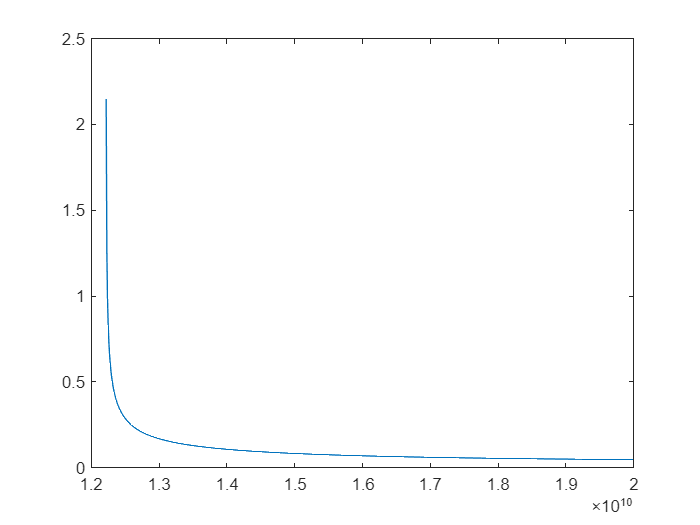

% =============
[a, f] = f_graph();
cla reset;
plot(f, a);

[k, f] = k_graph();

ans = 79

k_contrl_0 = find(k<(0.8*k_max));
k_contrl_1 = find(k<0.8*k_max)

k_contrl_1 =      1     2     3     4     5     6


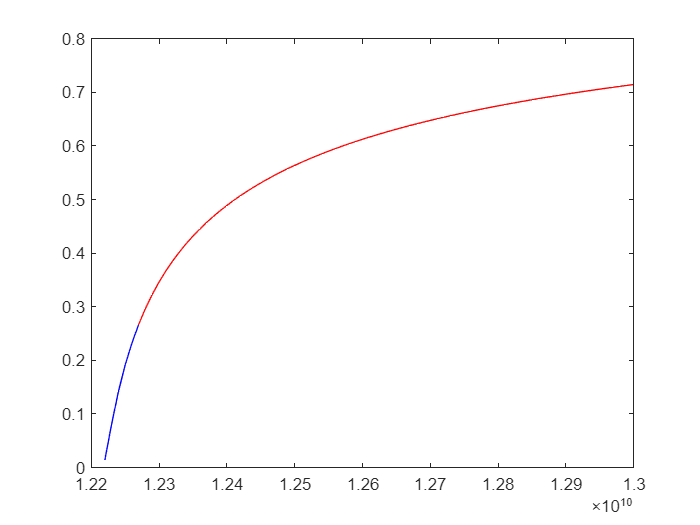

plot(f(1:k_contrl_1), k(1:k_contrl_1),'red', f(k_contrl_1), k(k_contrl_1), 'blue',f(k_contrl_1(end):end),k(k_contrl_1(end):end), 'red');

% plot(f, k);

function [a, f] = f_graph()
    f = 1222e7:1e7:20e9;
    a = zeros(1, length(f));
    for v = 1:length(f)
        a(v) = ((2.85*1e-7 *sqrt(f(v)))/sqrt(1 - (1.492*1e20)/f(v)^2))*((2.984*1e20)/(f(v)^2) + (1 - (1.22*1e10)/f(v))^2);
    end 
end

function [k, f] = k_graph()
    f = 1222e7:1e7:13e9;
    length(f)
    a = zeros(1, length(f));
    k = zeros(1, length(f));
    for v = 1:1:length(f)
        a(v) = ((2.85*1e-7 *sqrt(f(v)))/sqrt(1 - (1.492*1e20)/f(v)^2))*((2.984*1e20)/(f(v)^2) + (1 - (1.22*1e10)/f(v))^2);
        k(v) = exp(-2*a(v)*1);
    end 
end

% function [E, r] = E_graph(Ea1, Ea2, q, a, n)
%     r = linspace(0, 0.1, 1001);
%     E = zeros(1, 1001); 
%     k1 = 1/(4*pi*Ea1);
%     k2 = 1/(4*pi*Ea2);
%     for v = 0.0:0.0001:0.1
%         if v <= a
%             E(n) = (k1*q*v)/(a^3); 
%             n = n + 1;
%         else
%             E(n) = (k2*q)/(v^2);
%             n = n + 1;
%         end
%     end 
% end